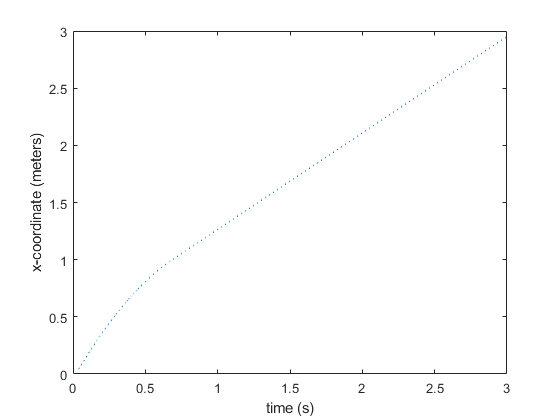

clf

% Description of the system
% A simulation of a physical system that depicts a simple object the size of a pinball 
% being launched by a spring. 

% SIMULATION PROPERTIES
n = 0.0001; % Step-size                                            
tf = 3; % Simulation time


% PHYSICAL PROPERTIES
% Spring based on Standard (10-148-1)
k_spring = 75; % Spring constant in N/m . Couldn't find information of the spring constant so this is guess work.
%equilibrium = 0.14; meters  
displacement = 0.07; % Contraction in meters

gravity = 9.81; % m/s^2
fc = 0.2; %   Coefficient of friction. metal on wood (0.2-0.6)

% Object based on a steel ball 
mass = 0.08; % kilogram 
object_Fmg = mass*-gravity;
object_Fnormal = mass*gravity;
Fb = gravity*mass*fc; % funkar inte. Blir negativa hastigheter och allt knasar.



% Begynnelsevilkor
Ax(1) = 0; % Begynnelsevilkor för objektets acceleration i x-led.
Ay(1) = object_Fmg + object_Fnormal; % Begynnelsevilkor för objektets acceleration i y-led

Vx(1) = 0; % Begynnelsevilkor för objektets hastighet i x-led.
Vy(1) = 0; % Begynnelsevilkor för objektets hastighet i y-led

x(1) = 0; % Begynnelsevilkor för objektets x-koordinat.
y(1) = 5; % Begynnelsevilkor för objektets y-koordinat.


% SIMULATION
for k = 2:(tf/n) 
       
    Fk = k_spring * displacement; % Hookes law: m*a = k_spring*displacement. 
    
    Fxtot = Fk - Fb; % Total force applied to the moving objec
    Fytot = object_Fmg + object_Fnormal; 
    
    %Ftot = Fk; % Total force applied to the moving object
    
    Ax(k) = Fxtot/mass; % Objektets acceleration i x-led . 
    Ay(k) = Fytot; % Objektets acceleration i y-led . 
    
    if x(k-1) < 1 % ytans längd
        % Objektet är i kontakt med fjädern och ytan
        if  displacement > 0 % while the object is in contact with the spring, calculate the following.       
            Vx(k) = euler1(Vx(k-1),Ax(k-1),n); % Objektets hastighet i x-led beror på den tidigare hastigheten samt accelerationen från fjädern 
            x(k) = euler1(x(k-1),Vx(k-1),n); % Objektets x-koordinat beror på dens tidigare position plus tidigare hastigheten
            
            displacement = euler1(displacement, -(Vx(k-1)),n); % displacement håller koll på hur länge fjädern är sammandragen, alltså dess kontakt med massan samt tillförelsen av acceleration&/hastighet. 
            if displacement < 0
                displacement = 0;
            end
            
        else % Objektet är ej längre i kontakt med fjädern men har kontakt med ytan. 
            Vx(k) = euler1(Vx(k-1),Ax(k-1),n); % Objektets hastighet 
            if Vx(k) <= 0
                Vx(k) = 0;
            end
            x(k) = euler1(x(k-1),Vx(k-1),n); % Objektets x-koordinat förflyttas med jämna mellanrum. 
        end
    else % Objektet har lämnat ytan
        object_Fnormal = 0; % ingen normalkraft
        Fb=0; % Ingen friktion
        %Ax(k) = 0;
        % Objektets hastighet i x-led
        Vx(k) = euler1(Vx(k-1),Ax(k-1),n); % Objektets hastighet i x-led beror på den tidigare hastigheten samt accelerationen från fjädern 
        x(k) = euler1(x(k-1),Vx(k-1),n); % Objektets x-koordinat beror på dens tidigare position plus tidigare hastigheten       
    end
        
    % Objektets hastighet i y-led
    Vy(k) = euler1(Vy(k-1),Ay(k-1),n);
    y(k) = euler1(y(k-1),Vy(k-1),n); % Objektets x-koordinat beror på dens tidigare position plus tidigare hastigheten
    
    
    
     
    time(k) = n*(k-1); % En vektor för tiden så att det hela kan plottas.
end
                                           
                                            
                                                                                        
plot(time, x,':')
xlabel('time (s)') 
ylabel('x-coordinate (meters)')

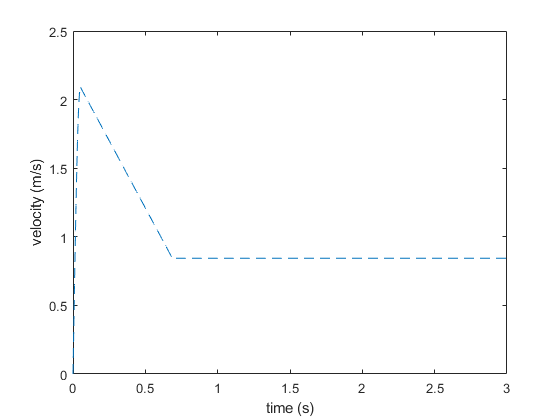


figure
plot(time, Vx,'--')
xlabel('time (s)') 
ylabel('velocity (m/s)')

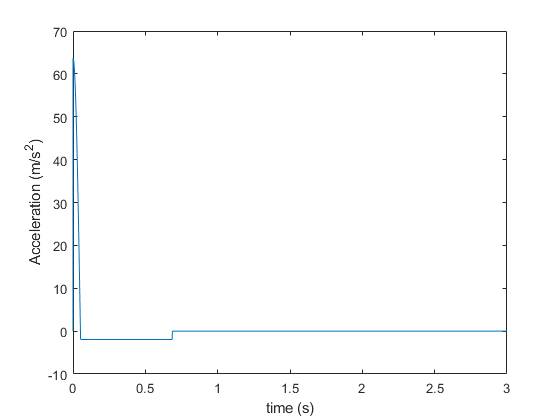


figure
plot(time, Ax,'-')
xlabel('time (s)') 
ylabel('Acceleration (m/s^2)')

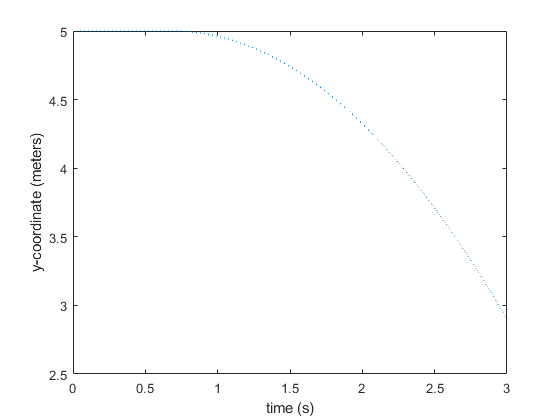


plot(time, y,':')
xlabel('time (s)') 
ylabel('y-coordinate (meters)')

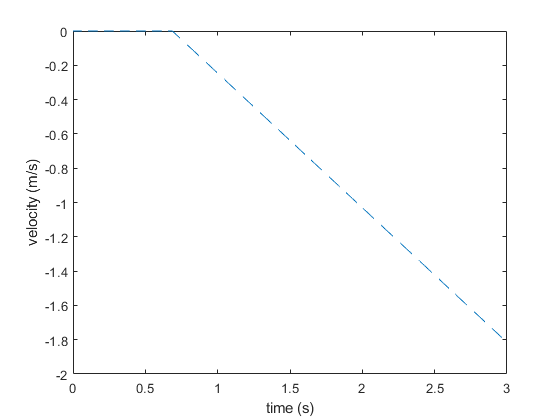


figure
plot(time, Vy,'--')
xlabel('time (s)') 
ylabel('velocity (m/s)')

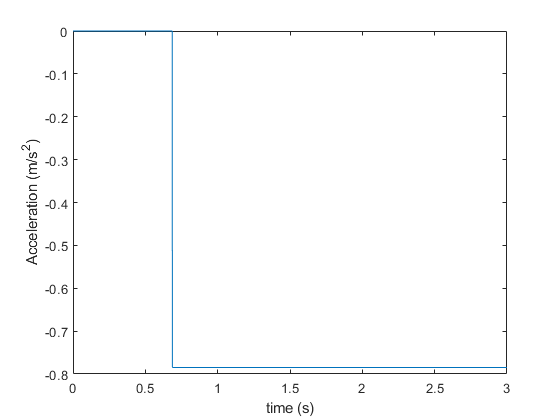


figure
plot(time, Ay,'-')
xlabel('time (s)') 
ylabel('Acceleration (m/s^2)')

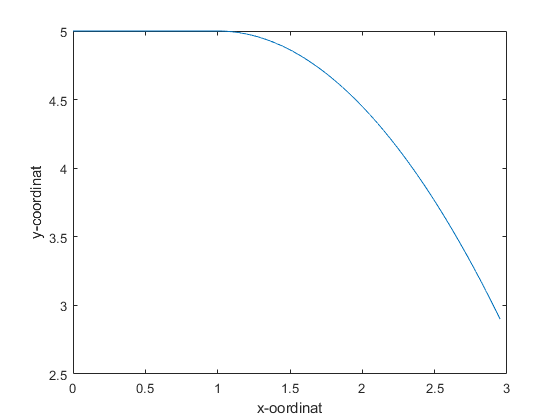


figure
plot(x, y,'-')
xlabel('x-oordinat') 
ylabel('y-coordinat')